The following edited based on:

        Copyright (c) 2014, Josh Bevan

        All rights reserved.

        This code is licensed under the BSD 3-Clause License, see License.txt for the full license.

August 2021, Lucia Zhang

# 1D Scalar Conservation Eqn solution

*-- using Discontinuous Galerkin*

### Discretization methods

- Arbitrary order spatial discretization: using a Legendre polynomial basis

- RK4 explicit time discretization

close all
clear all
tau = 2*pi();

Number of basis functions:

N = 5;  % Order of spatial discretization

## Problem definition

Here we attempt to solve the 1D scalar conservation eqn of the form:


$$\frac{\partial u}{\partial t} + \frac{\partial f(u)}{\partial x} = 0$$


where $f\left(u\right)$ is some flux function describing the "flow" of a conserved quantity. In this simplified case $f\left(u\right)=u$ giving us a linear PDE.

We will use periodic boundary conditions to examine **numerical dissipation effects**.

### Spatial discretization

Discretize the domain into K elements with K+1 nodes

Note: here we use a constant spacing, but it could be arbitrary

K = 32; % Number of elements

All the element boundaries, note *there are repeats* (twice, to be specific), since nodes have a coincident brother from an adjacent element, except at the domain boundaries.

xNode = 0:1/K:1;
elemBC = reshape(sort([xNode,xNode(2:end-1)]),2,K)';

- Let $u\left(x,t\right)$ be the exact solution on the domain $0\le x\le 1$

- Let $u\left(\ldotp ,0\right)=u_0 =\sin \left(2\pi x\right)$

- Let $V_h$ be the finite vector space of the shifed Legendre polynomials, up to order $N$

- Let $v$ be the approximate numerical solution consisting of a linear combination of basis functions ($\theta_N$ for the $N^{\textrm{th}}$ basis) in $V_h$ with scalar coefficients `BasisWeightN` (i.e. $\sum \;$`BasisWeightN `$\theta_N$)

- Let $\phi_N$ be the $N^{\textrm{th}}$ test function in the same vector space as the basis functions ($V_h$)

#### Right Hand Side (exact)

According to Cockburn,Shu 2001 Eqn 2.2

         6. let uh(.,0) be computed by $\int v \phi = \int u_0 \phi$ for each element ($x_j-\frac{1}{2} < x < x_j+\frac{1}{2}$)

We will numerically compute the RHS integral using ***Gauss-Legendre quadrature***, which is accurate up to s$2N-1$:

- Precalculate quadrature nodes and weights

[Qx,Qw] = gauss(N+1);

- Precompute Legendre values for fixed order quadrature points

L = zeros(N+1);
for m = 0:N
    temp = legendre(m,Qx); % Legendre() actually calculates the associated
    L(:,m+1) = temp(1,:)'; % Legendre polys, we only need m=0 (first row)
end

#### Left Hand Side - Mass

We can algebraically solve for the basis weights by analytically computing the LHS integral. The integrand is the inner product of v0 and the test function.

Since both are orthogonal in $V_h$, the result is a constant times the Kronecker product. The RHS is the discrete Legendre transform resulting from the Gauss-Legendre quadrature.

The simplified result is:


$$\overset{m}{a} =(m+.5) \sum_{i=1}^N Qw_i sin(2\pi \tilde{x}(x) ) \overset{n}{\phi}(x_i)$$


Some possible IVPs:

- Mollifier

- Gaussian w/ small discontinuity

- Periodic sin()

BasisWeights = zeros(K,N+1);
map = zeros(K,N+1);
for k = 1:K
    map(k,:) = (elemBC(k,2)-elemBC(k,1))*Qx/2 + (elemBC(k,1)+elemBC(k,2))/2;
    for m=0:N
        BasisWeights(k,m+1) = (m+.5)*sum(Qw.*max(0,exp(-(map(k,:)-0.5).^2/.01)-10^-1).*L(:,m+1)');
    end
end

Now that we have $u_0$

- we can begin *explicit time stepping (****Runge-Kutta ***$4^{\textrm{th}}$O*rder)* with the semi-discrete form of the PDE.

Because we have a linear flux function

- all the classic monotone flux schemes reduce to the *simple ****upwind flux*** i.e. $g\left(v-\left(x\right),\;v+\left(x\right)\right)=v-\left(x\right)$

### Assemble Semi-discrete

#### Assemble Semi-discrete matrix (local)

Self-references to the bases in the element. This is the sum of part of the upwind flux and the RHS integral in the original PDE.

The RHS integral portion is a strictly lower triangular matrix:

SelfStencil = 2*(toeplitz(mod(0:N,2),double(0:N<0)))-ones(N+1);

References to the bases in the upwind element, consists of the other part of the upwind flux:

UpwindStencil = ones(N+1);
UpwindStencil(2:2:N+1,:)=-1;

`LHSIntegral `is a purely diagonal matrix that depends on element size and the order of each basis:

LHSIntegral = reshape([1:2:2*N+1]'*(1./diff(xNode)),K*(N+1),1);

#### Assemble semi-discrete system (Global)

Build a unit stencil to pull the global diagonal pattern from

A = SelfStencil; A(N+2:2*N+2,1:N+1) = UpwindStencil;
DiagStencil = zeros(N+1,3*N+2);
for i=-(2*N+1):N
    DiagStencil(1:length(diag(A,i)),i+2*N+2) = diag(A,i);
end

Flip superdiagonal, since spdiags *truncates* the start of any oversized superdiagonals:

DiagStencil(:,2*N+2:3*N+2) = flipud(DiagStencil(:,2*N+2:3*N+2));

Build sparse reference matrix, by repeating unit stencil for each element:

A = spdiags(repmat(DiagStencil,K,1),-(2*N+1):N,K*(N+1),K*(N+1));

Periodic BCs, means the upwind element for k=1 is k=K 

A(1:N+1,K*(N+1)-N:K*(N+1)) = UpwindStencil;

Calculate new $\frac{\textrm{da}}{\textrm{dt}}$:

BasisWeights = reshape(BasisWeights',K*(N+1),1);

### Discretize in time

#### Temporal Parameters

deltaT  = 0.001;
saveT   = 0.01; % How often do we save the current state for plotting?
endT    = 5;
nsaveT  = floor(saveT/deltaT);
nT      = floor(endT/deltaT);
saved   = zeros(K*(N+1),(nT/nsaveT)+1);
saved(:,1)=BasisWeights;

#### Loop through time domain

i = 1;
for t = 1:1:nT
	% Periodically save system state for plotting
    if t/nsaveT==floor(t/nsaveT)    
        i= i+1;
        saved(:,i)=BasisWeights;
    end
	% RK4 explicit time discretization
    k1 = LHSIntegral.*(A*BasisWeights);
    k2 = LHSIntegral.*(A* (BasisWeights + deltaT*k1 /2) );
    k3 = LHSIntegral.*(A* (BasisWeights + deltaT*k2 /2) );
    k4 = LHSIntegral.*(A* (BasisWeights + deltaT*k3) );
    BasisWeights = BasisWeights +(deltaT/6)*(k1 + 2*k2 + 2*k3 + k4);
end

## Plotting

### Post processing

Add in element end points to make a "nice" looking plot. The Lobatto quad points are *not* used in the actual solution procedure:

Lobatto = zeros(N+3,N+1);
for m = 0:N
    temp = legendre(m,[-1; Qx; 1]);
    Lobatto(:,m+1) = temp(1,:)';
end

Reconstruct and plot the solution on the global domain.

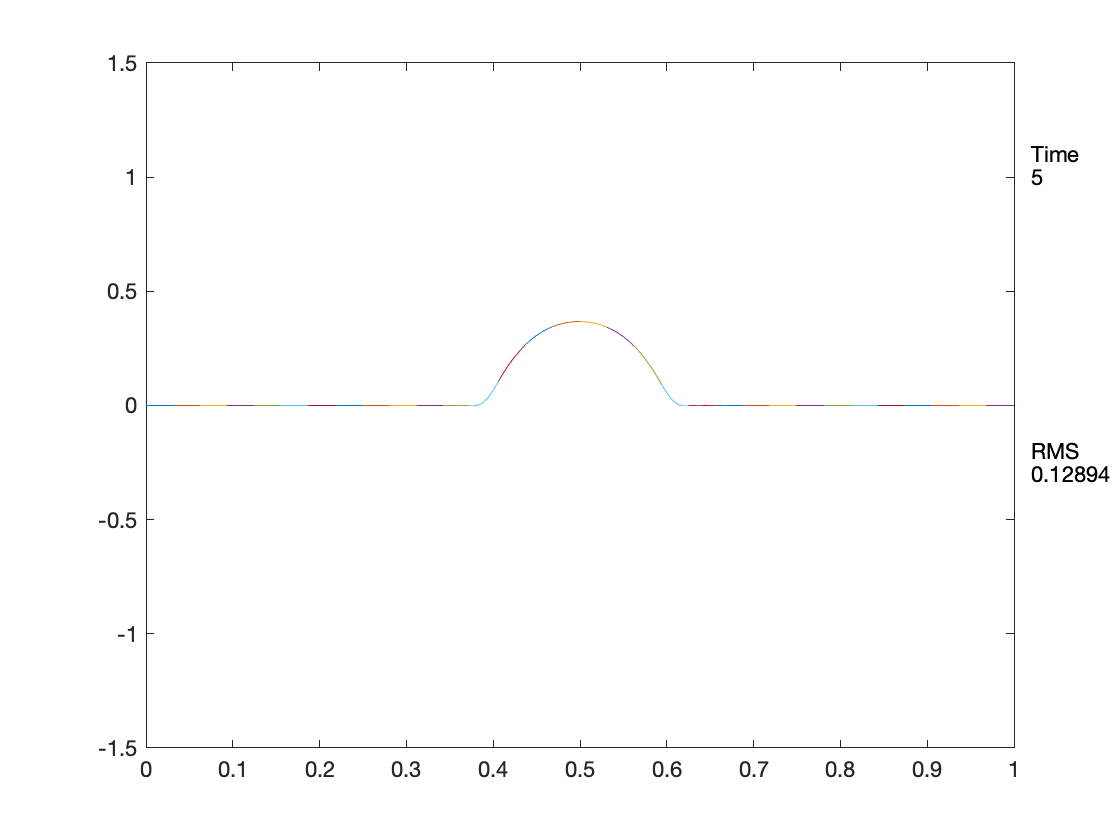

for i=1:length(saved)
    plot([elemBC(:,1) map elemBC(:,2)]',(Lobatto*reshape(saved(:,i),N+1,K)))
    axis([0 1 -1.5 1.5])
    text(1.02,-0.2,'RMS')
    text(1.02,-.3,num2str(rms(reshape(L*reshape(saved(:,i),N+1,K),K*(N+1),1))));
    text(1.02,1.1,'Time')
    text(1.02,1,num2str((i-1)*saveT));
    pause(.01)
end